%file = 'set4/rot';
file = 'potdng';
%ims = gpuArray(zeros(4, 1876, 2816, 3, 'double'));
ims = gpuArray(zeros(4, 2000-24, 1500-24, 3, 'double'));
for x=0:3
    deg = num2str(45 * x);
    %ims(x+1, :, :, :) = rgb2lin(imread(strcat('canoncut/', file, deg, '.tif')));
    ims(x+1, :, :, :) = rgb2lin(double(imread(strcat('cut/', file, deg, '.tif'))) ./ 255.0);
end
clear deg;
clear x;

imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

MeanRGB = squeeze(abs(imsfft(1, :, :, :))) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
CosRGB = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)
%CosRGB = ones(size(CosRGB)) .* min(CosRGB, [], 3);

clear imsfft;
clear i;

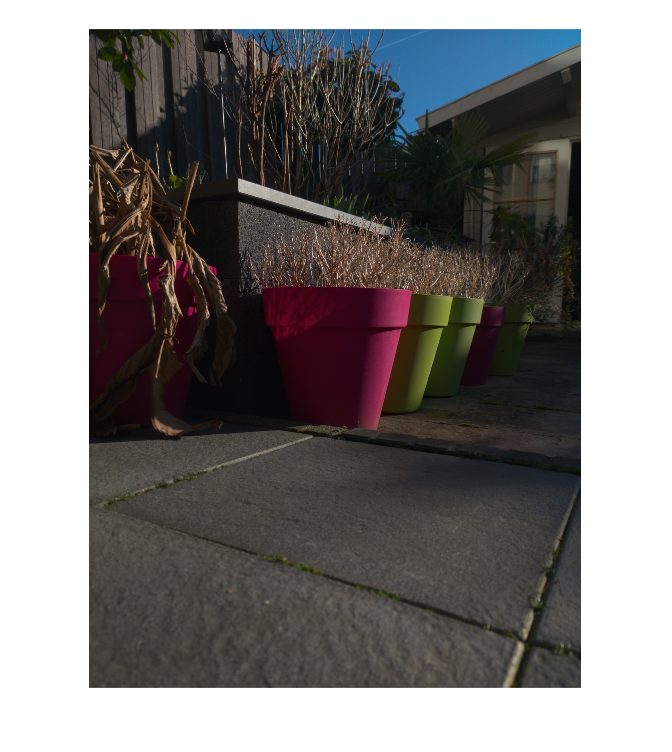

imshow(lin2rgb(gather(MeanRGB)));

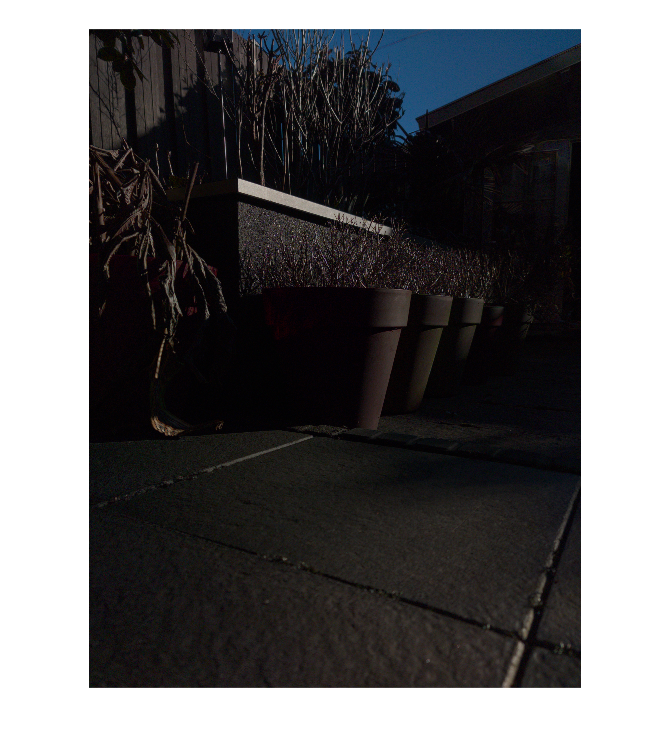

imshow(lin2rgb(gather(CosRGB)));

CosRGB2 = CosRGB;
imshow(lin2rgb(gather(100 .* CosRGB2)));
for c = 1:3
    for i = 1:4
        CosRGB2(:, :, c) = medfilt2(CosRGB2(:, :, c));
    end
end
imshow(lin2rgb(gather(100 .* CosRGB2)));

clear CosRGB2;
clear c;
clear i;

[qyTotal, qxTotal, ~] = size(MeanRGB);
divCount = 4;
qyPart = qyTotal / divCount;
qxPart = qxTotal / divCount;

As = gpuArray(ones([qyPart qxPart 25 2]));
bs = gpuArray(zeros([qyPart qxPart 25 1]));

%DiffuseFactor = gpuArray(zeros([qyPart qxPart 3]));
SpecularFactor = gpuArray(zeros([qyPart qxPart 3]));

for c = 1:3
    tic;
    for qy = 0:(divCount-1)
        yOffset = qyPart * qy;
        yCoords = (yOffset+1):(yOffset+qyPart);
        for qx = 0:(divCount-1)
            xOffset = qxPart * qx;
            xCoords = (xOffset+1):(xOffset+qxPart);
            
            % Fill matrix.
            for i = 1:25
                yDiff = floor((i - 1) / 5) - 2;
                xDiff = mod(i - 1, 5) - 2;
                
                yCoordsShift = max(1, min(qyTotal, yCoords + yDiff));
                xCoordsShift = max(1, min(qxTotal, xCoords + xDiff));
                
                % To-Do: Multiply by weight here.
                % As(:, :, i, 1) = 1;
                As(:, :, i, 2) = CosRGB(yCoordsShift, xCoordsShift, c);
                bs(:, :, i) = MeanRGB(yCoordsShift, xCoordsShift, c);
                
                [~, Spec] = solveparallel2x2(As, bs);
                %DiffuseFactor(yCoords, xCoords, c) = Dif;
                SpecularFactor(yCoords, xCoords, c) = Spec;
            end
        end
    end
    toc;
end

Elapsed time is 5.138193 seconds.
Elapsed time is 5.021607 seconds.
Elapsed time is 4.981685 seconds.



clear qyTotal;
clear qxTotal;
clear qyPart;
clear qxPart;
clear divCount;
clear As;
clear bs;
clear c;
clear qy;
clear qx;
clear yOffset;
clear yCoords;
clear xOffset;
clear xCoords;
clear i;
clear yDiff;
clear xDiff;
clear yCoordsShift;
clear xCoordsShift;
clear Dif;
clear Spec;

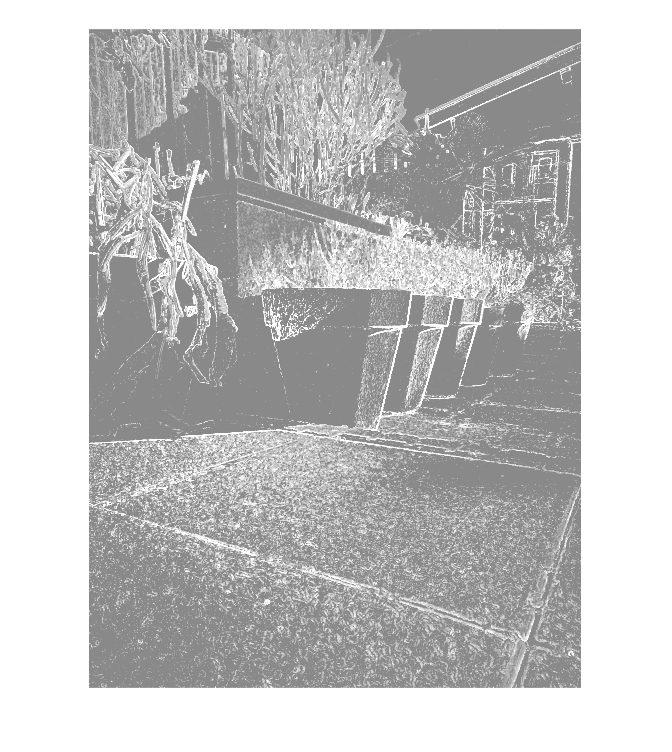

SpecularFactorScalar = max(max(1.0, SpecularFactor), [], 3);

imshow(lin2rgb(gather(0.25 .* SpecularFactorScalar)));


sigma_spatial = 2.33;
sigma_tonal = 0.02;

IterCount = 4;
tic;
for i = 1:IterCount
    SpecularFactorScalar = bilateralx(SpecularFactorScalar, MeanRGB, sigma_spatial, sigma_tonal);

    % Do Improvement Here.
end
toc;

Elapsed time is 5.515106 seconds.


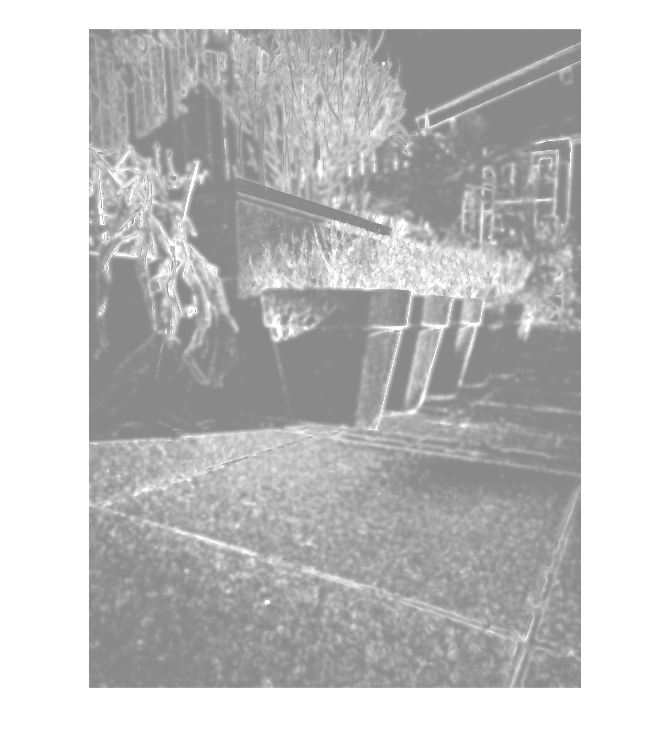

clear sigma_spatial;
clear sigma_tonal;
clear IterCount;
clear i;

imshow(lin2rgb(gather(0.25 .* SpecularFactorScalar)));

Specular = SpecularFactorScalar .* CosRGB;
Diffuse = max(0.0, MeanRGB - Specular);

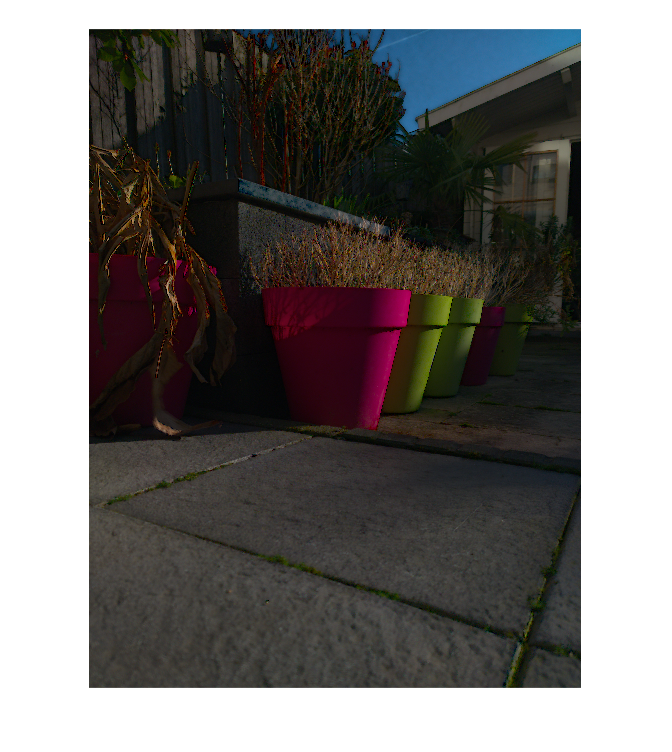

imshow(lin2rgb(gather(Diffuse)));

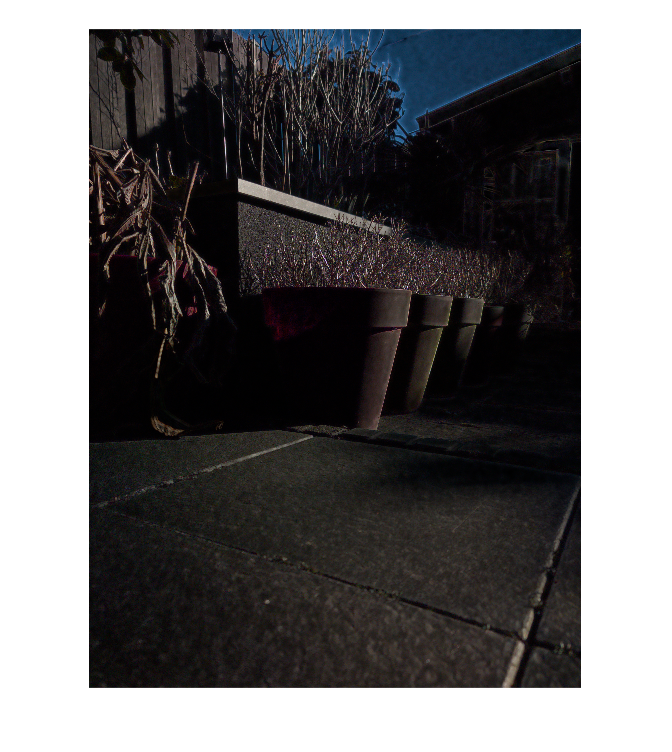

imshow(lin2rgb(gather(Specular)));

imshow(lin2rgb(gather(tonemapimage(Diffuse, 0.4, 1.0))));
imshow(lin2rgb(gather(100 .* Specular)));

[Y, X, ~] = size(MeanRGB);
DifFactor = zeros([Y X 3]);
CosFactor = zeros([Y X 3]);

A = ones([25 2]);
b = zeros([25 1]);

for y = 3:Y-2
    for x = 3:X-2
        for c = 1:3
            
            % Fill matrix.
            for i = 1:25
                y2 = y + floor((i - 1) / 5) - 2;
                x2 = x + mod(i - 1, 5) - 2;
                A(i, 2) = CosRGB(y2, x2, c);
                b(i) = MeanRGB(y2, x2, c);
            end
            
            ATA = A' * A;
            ATb = A' * b;
            
            res = ATA \ ATb;
            
            DifFactor(y, x, c) = res(1);
            CosFactor(y, x, c) = res(2);
        end
    end
end

clear y;
clear x;

imshow(lin2rgb(DifFactor));
imshow(lin2rgb(CosFactor));

Specular = max(CosFactor, [], 3) .* CosRGB;
Diffuse = MeanRGB - Specular;

min(max(CosFactor, [], 3), [], [1 2])

imshow(lin2rgb(Diffuse));
imshow(lin2rgb(Diffuse + Specular));
imshow(lin2rgb(Specular));

imshow(lin2rgb(DifFactor .* 1 + CosFactor .* CosRGB));
imshow(lin2rgb(DifFactor .* 1));
imshow(lin2rgb(CosFactor .* CosRGB));
% imshow(lin2rgb(0.5 .* CosFactor));

min(CosFactor, [], [1 2 3])
imshow(lin2rgb(0.5 .* max(CosFactor, [], 3)));

imshow(lin2rgb(MeanRGB(:, :, 1)));
imshow(lin2rgb(CosRGB(:, :, 1)));
imshow(lin2rgb(DifFactor(:, :, 1)));
imshow(lin2rgb(CosFactor(:, :, 1)));